%% Function definitions
fun_gaussian_sym = @(A,xy) A(1) * exp( - ( (xy{1}-A(4)).^2 + (xy{2}-A(5)).^2 ) / (2*A(3)^2) ) + A(2) + A(1) / A(6) * randn(size(xy{1},1),size(xy{1},2));
    % A = [amplitude, ofset, sigma, x0, y0, s2n]

fun_gaussian = @(A,xy) A(1) * exp( - ( (xy{1}-A(5)).^2 / (2*A(3)^2) + (xy{2}-A(6)).^2 / (2*A(4)^2) )  ) + A(2) + A(1) / A(7) * randn(size(xy{1},1),size(xy{1},2));
    % A = [amplitude, ofset, sx, sy, x0, y0, s2n]

getr = @(A,xy) sqrt( (xy{1}-A(4)).^2 + (xy{2}-A(5)).^2 );
getrr0 = @(A,xy) (1 - (getr(A,xy) / A(2) .* (getr(A,xy)<A(2))).^A(3)) .* (getr(A,xy)<A(2));
fun_box_z = @(A,xy) A(1) * getrr0(A,xy).^(3/2)  + A(1) / A(6) * randn(size(xy{1},1),size(xy{1},2));
    % A = [amplitude, r0, z, x0, y0, s2n]


fun_shotnoise = @(count,nxy) log(poissrnd(ones(size(nxy)) * count) ./ poissrnd( ones(size(nxy)) * count ./ exp(nxy) ));

%% Data setup
len_x = 73;
len_y = 73;
xy = {};
x = (1:1:len_x) ;
y = (1:1:len_y)';
[xy{1}, xy{2}] = meshgrid(x,y);

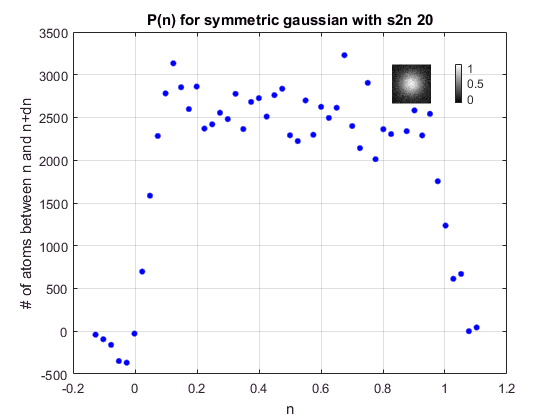

%% Symmetric Gaussian
A = [1, 0, 20, 50, 50, 20];
nxy = fun_gaussian_sym(A,xy);
[n_i, P_n] = extract_Pn(nxy,'bins',50,'plot_title',['P(n) for symmetric gaussian with s2n ', num2str(A(6))]);

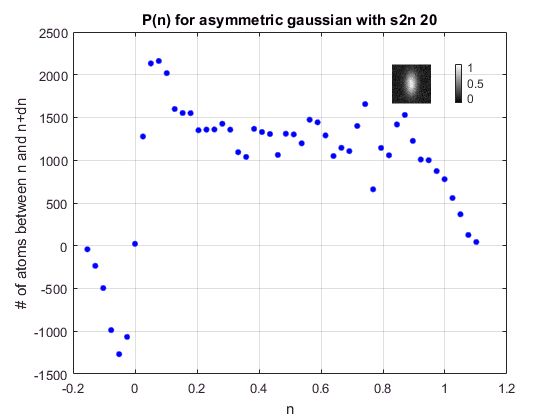

%% Asymmetric Gaussian
A = [1, 0, 10, 20, 50, 50, 20];
nxy = fun_gaussian(A,xy);
[n_i, P_n] = extract_Pn(nxy,'bins',50,'plot_title',['P(n) for asymmetric gaussian with s2n ', num2str(A(7))]);

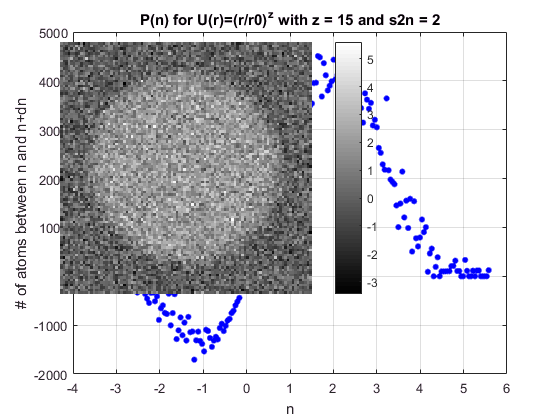

%% Box with (r/r0)^z - z dependence
A = [2, 40, 15, 50, 50, 2];
nxy = fun_box_z(A,xy); 
[n_i, P_n] = extract_Pn(nxy,'bins',200,'plot_nxy_pos',[.1 .3 .6 .6],'plot_title',['P(n) for U(r)=(r/r0)^z with z = ',num2str(A(3)),' and s2n = ',num2str(A(6))]);

z = 2:2:20;

% for i = 1:length(z)


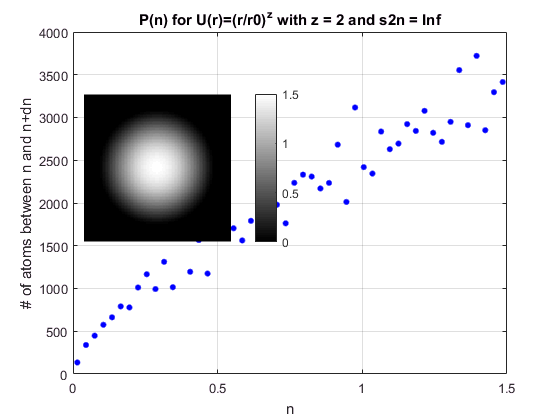

%% Harmonic trap
A = [1.5, 40, 2, 50, 50, inf];
nxy = fun_box_z(A,xy); 
% nxy = fun_shotnoise(700,nxy);
[n_i, P_n] = extract_Pn(nxy,'bins',50,'plot_nxy_pos',[.15 .4 .4 .4],'plot_title',['P(n) for U(r)=(r/r0)^z with z = ',num2str(A(3)),' and s2n = ',num2str(A(6))]);

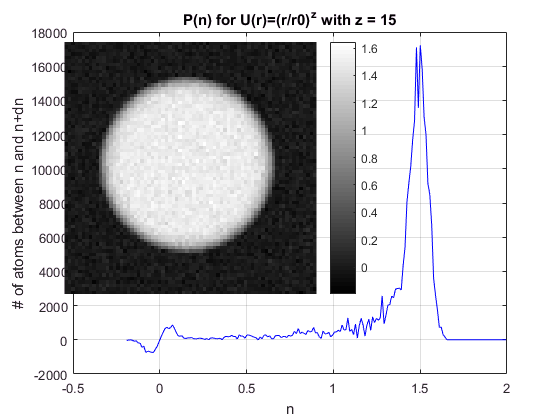

%% Box with (r/r0)^z - averaging
A = [1.5, 26, 15, 72/2, 72/2, 30];
A_g = [1.5, 40, 10, 50, 50, 20];
count = 500;
avg = 22;

nxy = fun_box_z(A,xy); 
nxy_g = fun_box_z(A_g,xy);
nxy_p = fun_shotnoise(count,nxy);
nxy_avg = fun_shotnoise(count,nxy) / avg; for i = 2:avg, nxy_avg = nxy_avg + fun_shotnoise(count,nxy) / avg; end

% nxy = poissrnd(round(nxy));
[n_i, P_n] = extract_Pn(nxy,'nmax',2,'bins',200,'plot_nxy_pos',[.1 .3 .6 .6],'plot_title',['P(n) for U(r)=(r/r0)^z with z = ',num2str(A(3))]);

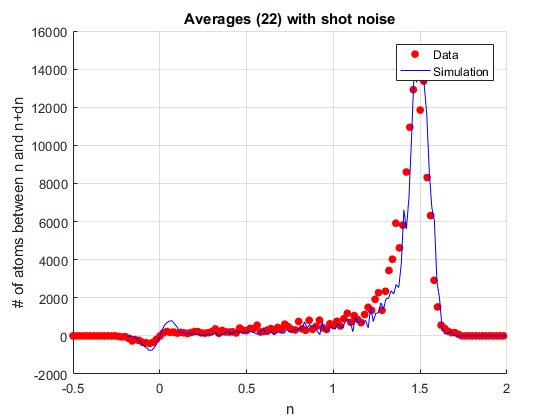


% figure; ax1 = subplot(2,2,1); ax2 = subplot(2,2,2); ax3 = subplot(2,2,3); ax4 = subplot(2,2,4);
% [n_i, P_n] = extract_Pn(nxy,'nmax',2,'bins',200,'plot_nxy_pos',[.2 .5 .4 .4],'plot_title',['No noise'],'plot_axis',ax1,'plot_nxy',0);
% [n_i, P_n] = extract_Pn(nxy_g,'nmax',2,'bins',200,'plot_nxy_pos',[.2 .5 .4 .4],'plot_title',['Gaussian noise with s2n = ',num2str(A_g(6))],'plot_axis',ax2,'plot_nxy',0);
% [n_i, P_n] = extract_Pn(nxy_p,'nmax',2,'bins',200,'plot_nxy_pos',[.2 .5 .4 .4],'plot_title',['Shot noise with Ncount = ',num2str(count)],'plot_axis',ax3,'plot_nxy',0);
% [n_i, P_n] = extract_Pn(nxy_avg,'nmax',2,'bins',200,'plot_nxy_pos',[.2 .5 .4 .4],'plot_title',['Averages (',num2str(avg),') with shot noise'],'plot_axis',ax4,'plot_nxy',0);
% 
figure; ax = subplot(1,1,1);
hold on;
plot(n_i_awe,P_n_awe,'r.','MarkerSize',20);
[n_i, P_n] = extract_Pn(nxy_avg,'nmax',2,'bins',150,'plot_nxy_pos',[.2 .5 .4 .4],'plot_title',['Averages (',num2str(avg),') with shot noise'],'plot_axis',ax,'plot_nxy',0);
legend({'Data','Simulation'});

%% Effects of atom number fluctuations
maxOD = 1.8:0.05:2.2;
count = 500;

figure; subplot(1,1,1); hold on;
for i = 1:length(maxOD)
    A = [maxOD(i), 40, 2, 50, 50, inf];
    nxy = fun_box_z(A,xy);
    nxy = fun_shotnoise(count,nxy);
    [n_i,P_i] = extract_Pn(nxy,'plot',0);
    plot(n_i / (sum(nxy(:))),P_i,'.','MarkerSize',10);
end
hold off;
title('Simulation: Rescaling the x axis by total atom number');